%%Q2
clear;clc;close all;

T = 0.01;

%Model paramters and Matrice
A = 1; H =1;
f = @(x) A*x;
h = @(x) H*x;
Q = 1.5; R = 3;

% Prior for p(x0)
x_0 = 2; P_0 = 9;

% number of time steps
N = 30;

% number of particles
ParticleNum = 50;

% bResample = true;

% sigma for the approximation in plotPostPdf
sigma = 1;

X = genLinearStateSequence(x_0, P_0, A, Q, N);
Y = genLinearMeasurementSequence(X, H, R);


% [xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, T, Q, S, h, R, genSigmaPoints, 'UKF');
% do not have S here


% filter data
[xf, Pf] = kalmanFilter(Y, x_0, P_0, A, Q, H, R);

% function plotPartTrajs(k, Xk, Xkmin1, ~, j)
% Inputs:
%   k           time instance index
%   Xk          [n x N] N particles of dimension n to approximate p(x_k).
%   Xkmin1      [n x N] N particles of dimension n to approximate p(x_k-1).
%   Wk          [1 x N] Corresponding weights.
%   j           Index vector such that Xk(:,i) = Xkmin1(:,j(i))

myplot = @(k, Xk, Xkmin1, j) plotPartTrajs(k, Xk, Xkmin1,[], j);
% pdfplot = @(k, Xk, Wk, xf, Pf, bResample, sigma, ax) plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax);

% figure;hold on;
[xfpre, Pfpre, Xpre, Wpre] = pfFilter(x_0, P_0, Y, f, Q, h, R, ParticleNum, 1, myplot);
% title('Resample')
% figure;hold on;
[xfp, Pfp, Xp, Wp] = pfFilter(x_0, P_0, Y, f, Q, h, R, ParticleNum, 0, myplot);
% title('Noresample')

%xfp is mean and Pfp is covariance
disp('KF mse:')

KF mse:


mse(X(2:end)-xf)

ans = 1.4647

disp('PF with resample')

PF with resample


mse(X(2:end)-xfpre)

ans = 1.9206

disp('PF without resample')

PF without resample


mse(X(2:end)-xfp)

ans = 4.8994

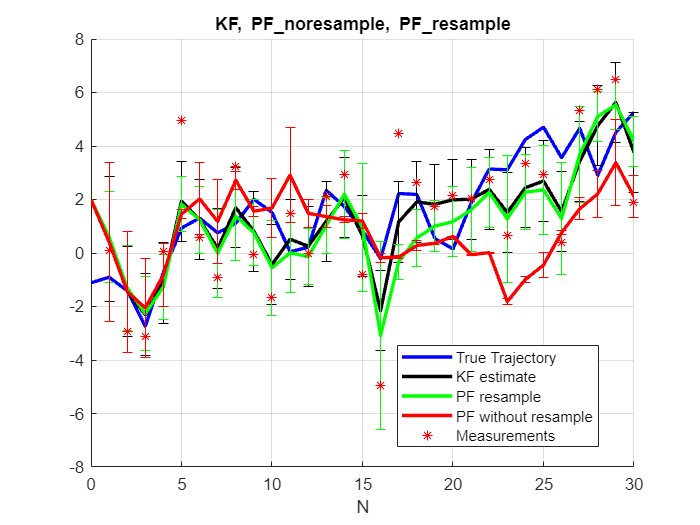



%% plot position
figure;hold on; grid on;
range= 0:1:N;
%True state
p_true = plot(range, X, 'b', 'LineWidth',2, 'DisplayName','True Trajectory');
p_KF = plot(range, [x_0 xf],  'Color','k', 'LineWidth',2, 'DisplayName','KF estimate');
errorbar(1:N,xf,squeeze(Pf(1,1,:))','Color','k','DisplayName','KF cov'); 
p_PFre = plot(range, [x_0 xfpre], 'Color','g', 'LineWidth',2, 'DisplayName','PF resample');
errorbar(1:N,xfpre,squeeze(Pfpre(1,1,:))','Color','g','DisplayName','PF resample cov'); 
p_PF  = plot(range, [x_0 xfp],  'Color','r', 'LineWidth',2, 'DisplayName','PF without resample');
errorbar(1:N,xfp,squeeze(Pfp(1,1,:))','Color','r','DisplayName','PF without resample cov'); 
p_measure = plot(1:N, Y, '*r', 'DisplayName','Measurements');
% p5 = plot(range, H*[x_0 xf] + 3*sqrt([P_0(1) squeeze(Pf(1,1,:))']), '--b', 'DisplayName','+3-sigma level');
% p6 = plot(range, H*[x_0 xf] - 3*sqrt([P_0(1) squeeze(Pf(1,1,:))']), '--b', 'DisplayName','-3-sigma level');
xlabel('N');
legend([p_true p_KF p_PFre p_PF p_measure],'Location','best');
title('KF, PF\_noresample, PF\_resample')

% fp.savefig('q2a-pos')




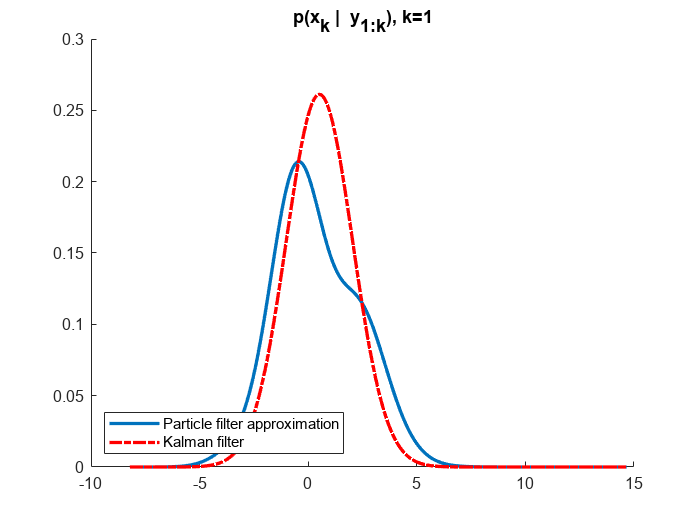

% Define the time instances
time_instances = [1, 14, 28];

for k = 1:length(time_instances)
    % Get the current time instance
    current_k = time_instances(k);

    % Create a new figure
    figure;
    hold on;

    % Call pdfplot function for each filter
    plotPostPdf(current_k, Xp(:, :, current_k), Wp(:, current_k)', xf(:, current_k), Pf(:, :, current_k), false, sigma, gca);
    plotPostPdf(current_k, Xpre(:, :, current_k), Wpre(:, current_k)', xfpre(:, current_k), Pfpre(:, :, current_k), true, sigma, gca);
    plot(range, [x_0 X(:, current_k)], 'b', 'LineWidth', 2, 'DisplayName', 'True Trajectory');

    % Set the title and legend
    title(['Time Instance k = ' num2str(current_k)]);
    legend('show');

    % Adjust the axis limits if necessary
    xlim(ax(1:2));
    ylim(ax(3:4));s
end





pdfplot()

ts = 45; %19

fig = figure('Color','white','Position',[675  549  570  s420]);
hold on, grid on;
set(fig, 'Name', ['p_',num2str(ts), '_', 'SIR']);

p1 = plot( X([ts,ts]+1), [0,max([pApprox,pApprox_r])*1.2],'--' , 'Color','b','LineWidth', 4, 'DisplayName', 'True state')
p1.Color = [p1.Color 0.2];

[Xl, KF, pApprox_r] = plotFunc_handle_r (ts, Xpre(:,:,ts), Xpre(:,:,ts-1), Wpre(:,ts)', []);
plot( Xl, pApprox_r, 'Color',cp(5,:), 'LineWidth', 2, 'DisplayName','PF estimate with resampling')

[Xl, KF, pApprox]   = plotFunc_handle   (ts, Xp(:,:,ts),  Xp(:,:,ts-1),  Wp(:,ts)',  []);
plot( Xl, pApprox,   'Color',cp(3,:), 'LineWidth', 2, 'DisplayName','PF estimate without resampling')

plot( Xl, KF, '-.',  'Color','k',     'LineWidth', 2, 'DisplayName','Kalman filter')
legend( 'Location', 'southeast')
title(['p(x_k |  y_{1:k}),   k=', num2str(ts)])
ylim([0,max([pApprox,pApprox_r])*1.2])
xlim( X(ts) + Pf(1,1,ts)^0.5*[-5 5])
% fp.savefig(sprintf('q2a-dist-%d',ts))
% Define the time instances
time_instances = [1, 19, 38];

for k = 1:length(time_instances)
    % Get the current time instance
    current_k = time_instances(k);

    % Create a new figure
    figure;
    hold on;

    % Call pdfplot function for each filter
    pdfplot(current_k, Xp(:, :, current_k), Wp(:, current_k), xf(:, current_k), Pf(:, :, current_k), false, sigma, gca);
    pdfplot(current_k, Xpre(:, :, current_k), Wpre(:, current_k), xfpre(:, current_k), Pfpre(:, :, current_k), true, sigma, gca);
    plot(range, [x_0 X(:, current_k)], 'b', 'LineWidth', 2, 'DisplayName', 'True Trajectory');

    % Set the title and legend
    title(['Time Instance k = ' num2str(current_k)]);
    legend('show');

    % Adjust the axis limits if necessary
    xlim(ax(1:2));
    ylim(ax(3:4));
end


%% 2B
close all;

ParticleNum = 50;

bAlpha = true;

ploth = @(k, Xk, Xkmin1, Wk, j) plotPartTrajs(k, Xk, Xkmin1, Wk, j, bAlpha);

figure('Color','white','Position',[292   475  1165   422]);

subplot(1,2,1)
hold on, grid on;
bResample = true;
pfFilter(x_0, P_0, Y, f, Q, h, R, ParticleNum, bResample, ploth,[]);
plot(0:length(X)-1, X, 'Color',cp(2,:),'LineWidth', 2)
xlabel 'time step', ylabel 'state value', title 'Particle trajectories with resampling'
ylim([-8,12])

subplot(1,2,2)
hold on, grid on;
bResample = false;
pfFilter(x_0, P_0, Y, f, Q, h, R, ParticleNum, bResample, ploth ,[]);
plot(0:length(X)-1, X, 'Color',cp(2,:),'LineWidth', 2)
xlabel 'time step', ylabel 'state value', title 'Particle trajectories without resampling'
ylim([-32,24])
% fp.savefig('q2b-w')
% fp.savefig('q2b-nw')